**Task 1 a)**

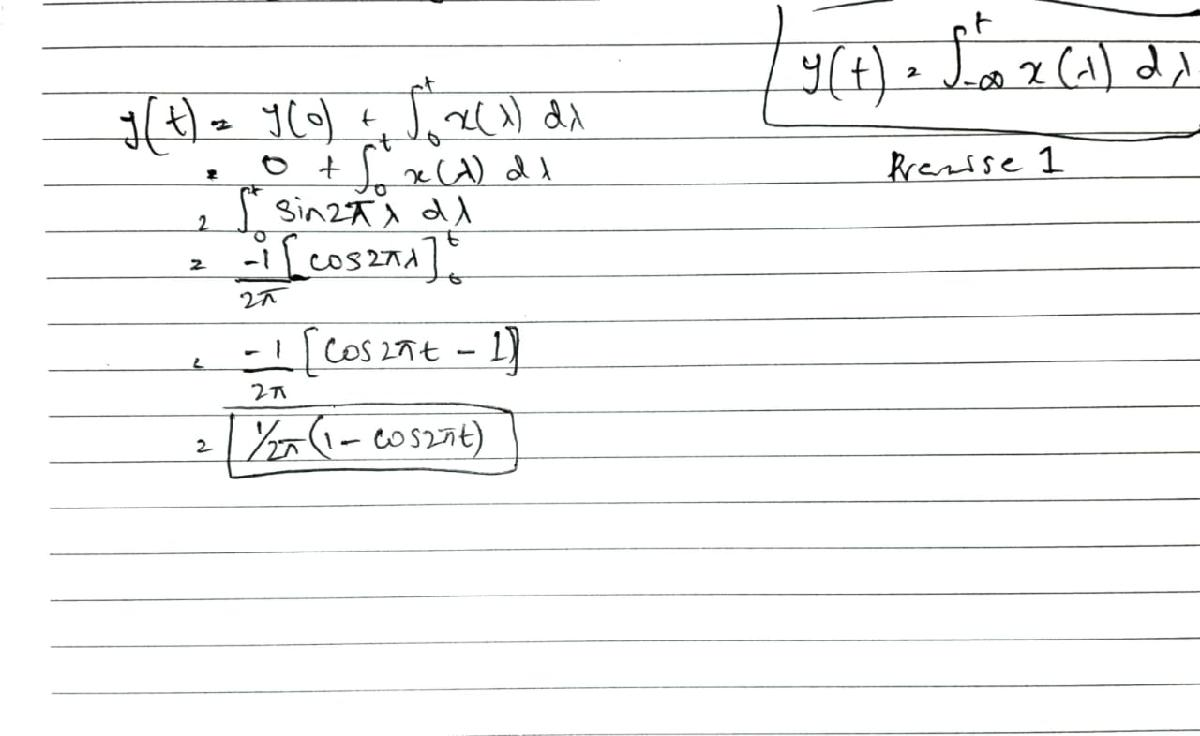

**Task 1 b)**

syms A f0 t pi
xt = A*sin(2*pi*f0*t);
yt = int(xt,'t')

$$yt = -\frac{A\,\cos\left(2\,f_{0}\,\pi \,t\right)}{2\,f_{0}\,\pi }$$

yt = int(xt,'t',[0,t]) 

$$yt = \frac{A\,{\sin\left(f_{0}\,\pi \,t\right)}^{2}}{f_{0}\,\pi }$$

% yes this result is the same as the one I did by hand.
% expanding using the double angle identity gives the exact same result

**Task 1 c)**

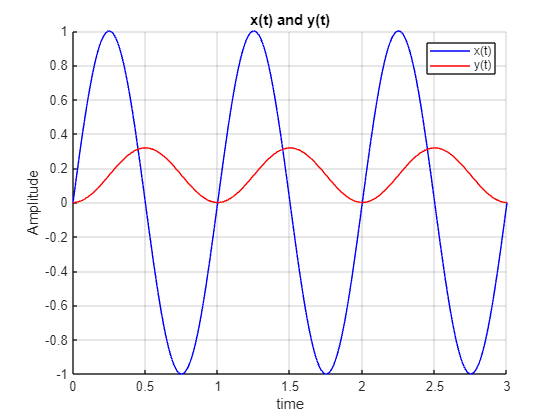

t = 0:0.01:3;
A = 1; f0 = 1;
xt = A*sin(2*pi*f0*t);
yt = ((A*sin(f0*pi*t)) .^ 2) / (f0*pi);

figure;
hold on;
grid on;

plot(t, xt, "b");
plot(t, yt, "r");

xlabel("time");
ylabel("Amplitude");
title("x(t) and y(t)");
legend("x(t)", "y(t)");

**Task 1 d)**

a = [1 2 3 4 5];
b = cumsum(a)

b =      1     3     6    10    15


% b_i = sum of all elements from b_1 to b_i

**Task 1 e) and f)**

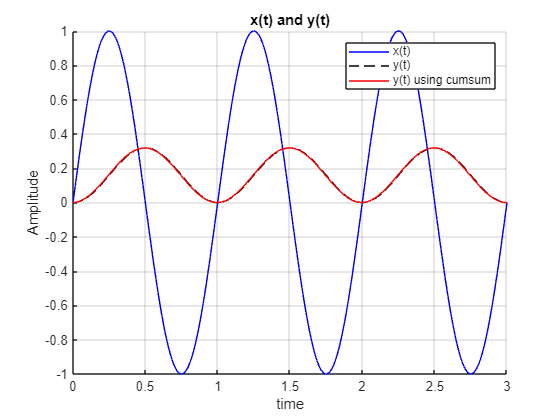

dt = 0.01;
t = 0:dt:3;
A = 1; f0 = 1;
xt = A*sin(2*pi*f0*t);
yt = ((A*sin(f0*pi*t)) .^ 2) / (f0*pi);
yt_cs = cumsum(xt) * dt;

figure;
hold on;
grid on;

plot(t, xt, "b");
plot(t, yt, "black--");
plot(t, yt_cs, "red");

xlabel("time");
ylabel("Amplitude");
title("x(t) and y(t)");
legend("x(t)", "y(t)", "y(t) using cumsum");

% It is almost same as the graph of the integrated function

**Task 1 g)**

Numerical integration is useful in real-world situations where we deal with data points instead of a clear formula. It is easier and faster for solving complex problems where exact solutions are hard to find. It works well with noisy or messy data, handles high-dimensional problems, and is used in real-time applications like signal processing. It’s simple to use and very helpful in fields like engineering and science.

**Task 1 h)**

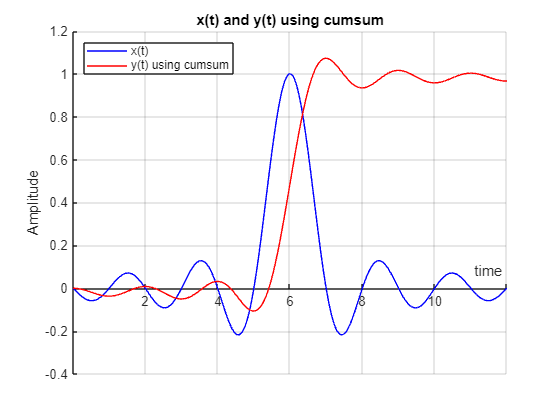

dt = 0.01;
t = 0:dt:12;
xt = sinc(t-6);
yt = cumsum(xt) * dt;

figure;
hold on;
grid on;

plot(t, xt, "b");
plot(t, yt, "r");

xlabel("time");
ylabel("Amplitude");
title("x(t) and y(t) using cumsum");
legend(["x(t)", "y(t) using cumsum"], "location", "northwest")
ax = gca; % Get current axes
ax.XAxisLocation = 'origin'; 

**Task 1 i)**

a = [1 2 3 4 5];
b = diff(a)

b =      1     1     1     1


% a_i = a_(i+1) - a_i

**Task 1 j)**

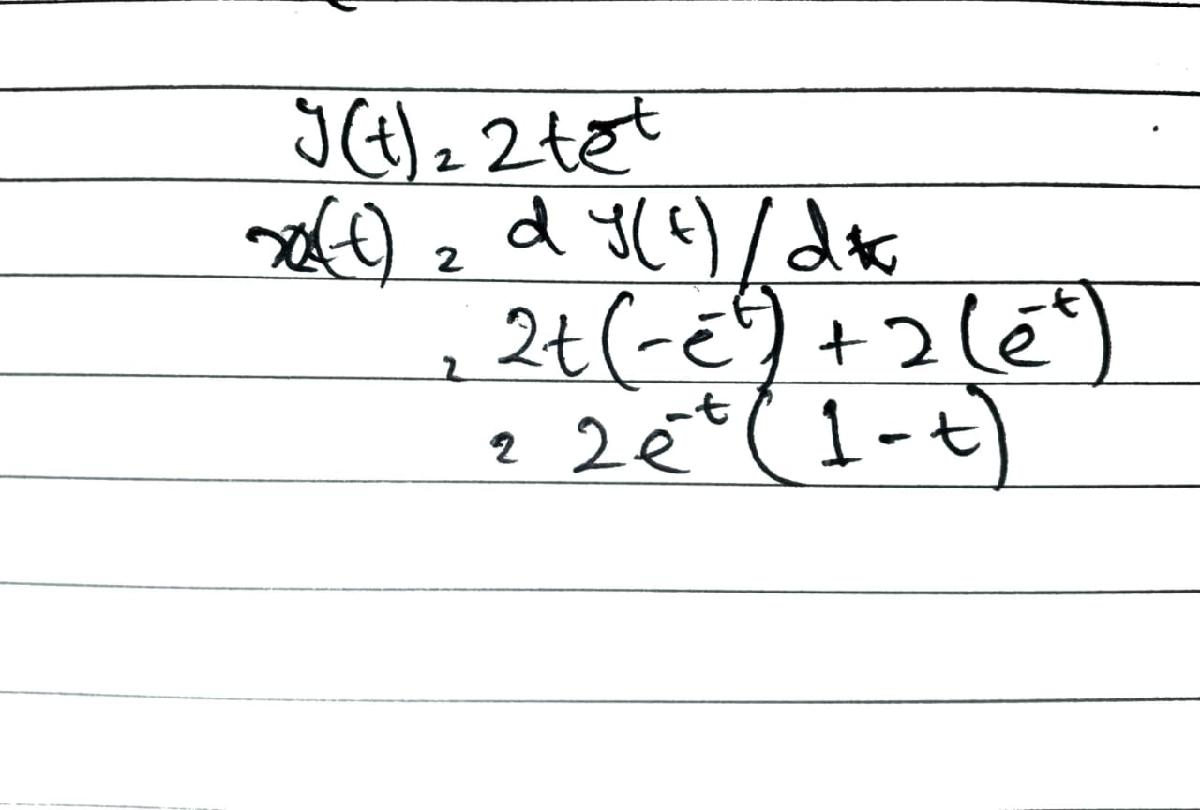

**Task 1 k) and l)**

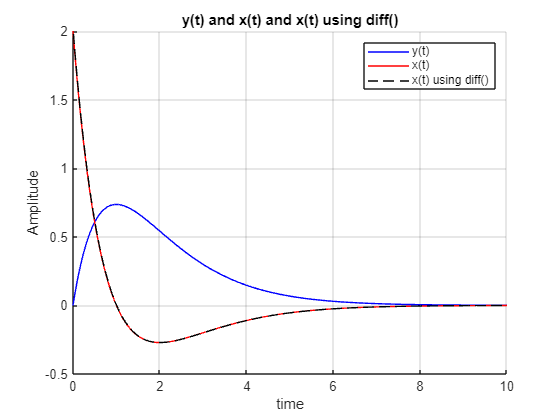

dt = 0.01;
t = 0:dt:10;
yt = 2 * t .* exp(-1* t);
xt = 2 * exp(-t) .* (1-t);
xt_df = [nan diff(yt)/dt];

figure;
hold on;
grid on;

plot(t, yt, "b");
plot(t, xt, "r");
plot(t, xt_df, "black--");

xlabel("time");
ylabel("Amplitude");
title("y(t) and x(t) and x(t) using diff()");
legend("y(t)", "x(t)", "x(t) using diff()");

% It is the same as the differentiated function

**Task 1 m)**

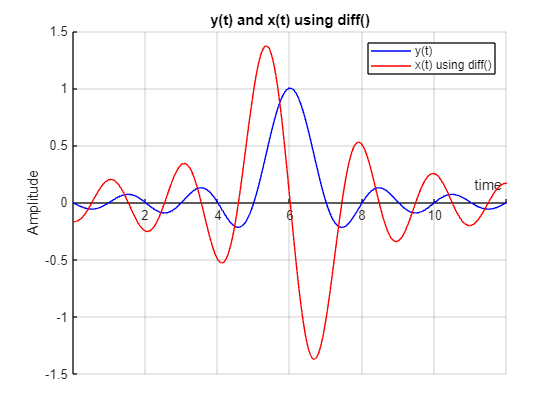

dt = 0.01;
t = 0:dt:12;
yt = sinc(t-6);
xt_df = [nan diff(yt)/dt];

figure;
hold on;
grid on;

plot(t, yt, "b");
plot(t, xt_df, "red");

xlabel("time");
ylabel("Amplitude");
title("y(t) and x(t) using diff()");
legend("y(t)","x(t) using diff()");
ax = gca; % Get current axes
ax.XAxisLocation = 'origin';

**POST LAB**